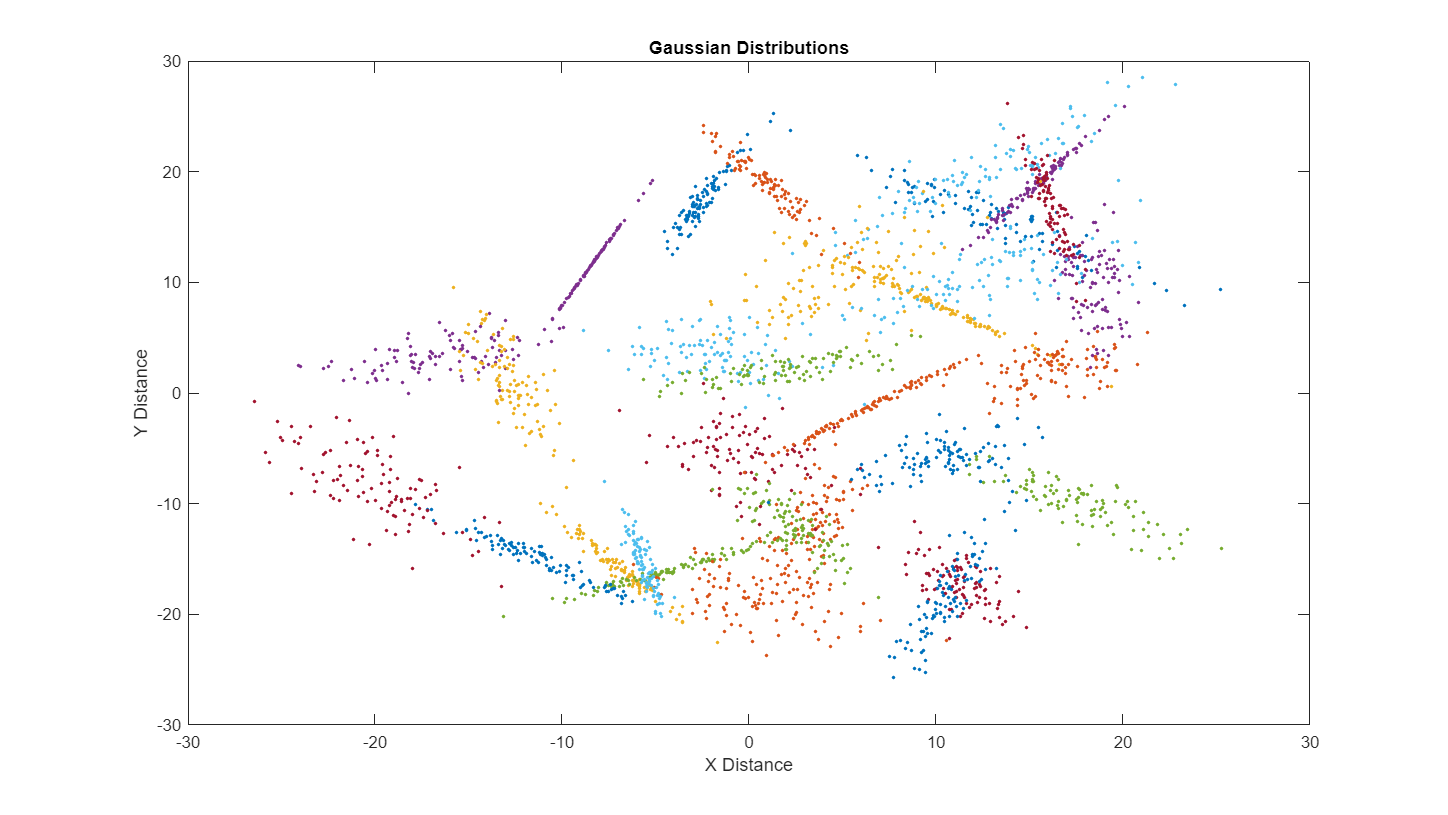

num_of_clusters = 30;  
start_range_mean = -20;
end_range_mean = 20;
start_range_var = 0;
end_range_var =  10;
data_points_per_cluster = 100;
no_of_users = num_of_clusters * data_points_per_cluster;   

power_threshold = 20;
height_threshold = 0.5;
bw_uav  = 5;
alpha = 0.5;
chan_capacity_thresh = 10;
var_n = 0.5;

P_bs = 50;
P_uav = power_threshold;
bw_bs = 2;
bw_uav  = 5;
h_relay= 1;
h_bs = 0.1;
capacity_thresh = 1;

data = generate_data(num_of_clusters, start_range_mean, end_range_mean, start_range_var, end_range_var, data_points_per_cluster);
X = data(:, 1);
Y = data(: ,2);

figure('Name', 'Gaussian Clusters', 'units','normalized','outerposition', [0 0 1 1]);
for i=1:num_of_clusters
    plot(data((i-1)*100 + 1: (i)*100, 1), data((i-1)*100 + 1: (i)*100, 2), '.');
    hold on;
end

hold off;
title('Gaussian Distributions');
xlabel('X Distance');
ylabel('Y Distance');

K means algorithm to place the cluster UAVs

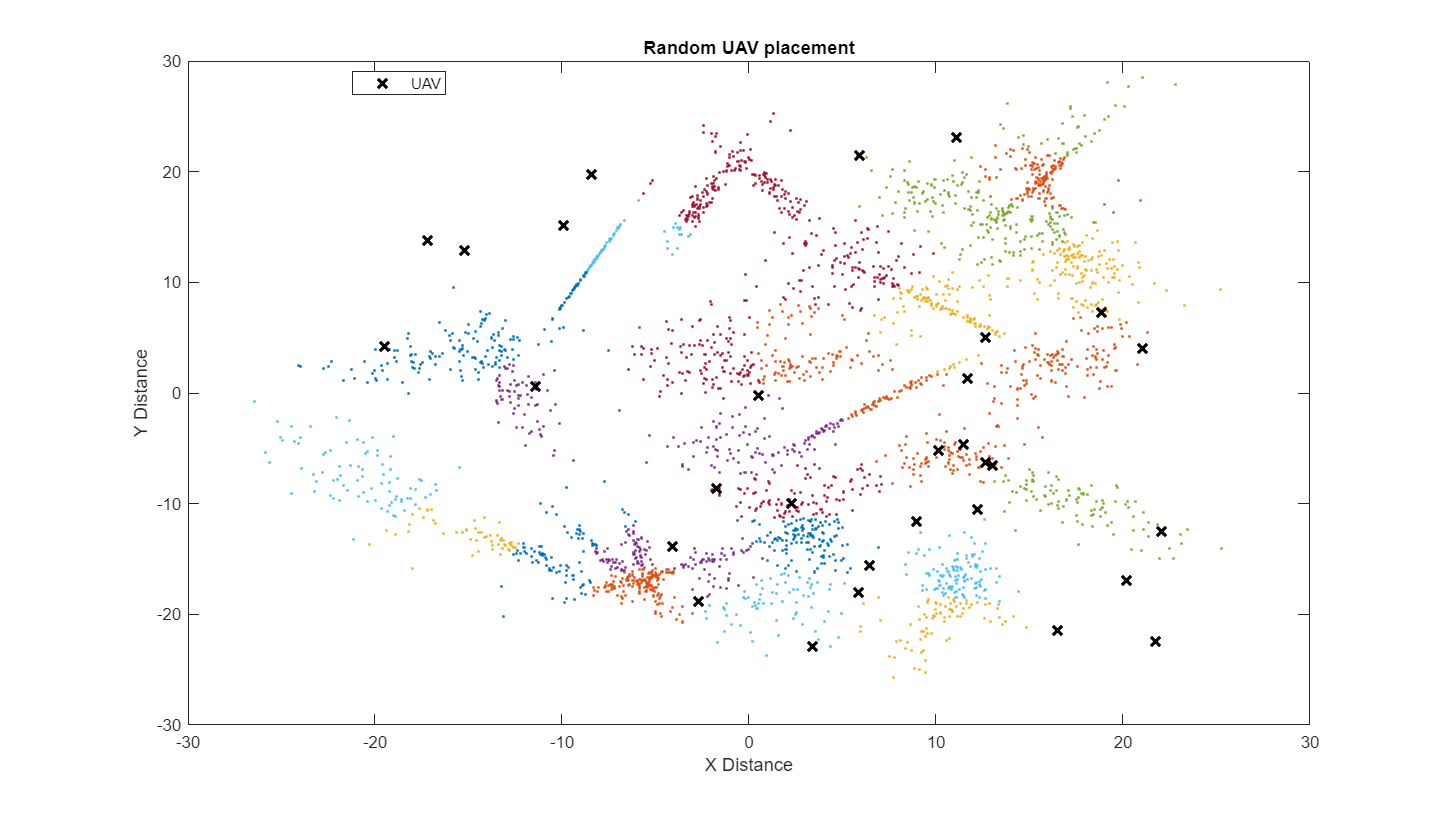

num_of_centroids = num_of_clusters;
[idx, centroids] = kmeans(data, num_of_centroids);

k_means_clusters = cell(num_of_centroids, 1);
for i = 1:num_of_centroids
    k_means_clusters{i} = [X(idx==i),Y(idx==i)];
end

start_range_random = start_range_mean - sqrt(end_range_var);
end_range_random = end_range_mean + sqrt(end_range_var);
X_random = start_range_random + (end_range_random - start_range_random) * rand(num_of_clusters, 1);
Y_random = start_range_random + (end_range_random - start_range_random) * rand(num_of_clusters, 1);
random_centroids = [X_random, Y_random];

figure('Name', 'Random UAV placement', 'units','normalized','outerposition',[0 0 1 1]);

gscatter(X, Y, idx);
hold on;
p_centroids_random = plot(random_centroids(:,1), random_centroids(:,2), 'kx', 'MarkerSize', 8, 'LineWidth', 2, 'DisplayName','UAV'); 
hold off;

legend(p_centroids_random, 'UAV');
title('Random UAV placement');
xlabel('X Distance');
ylabel('Y Distance');

## Plotting the UAVs on the centroids of K-Means

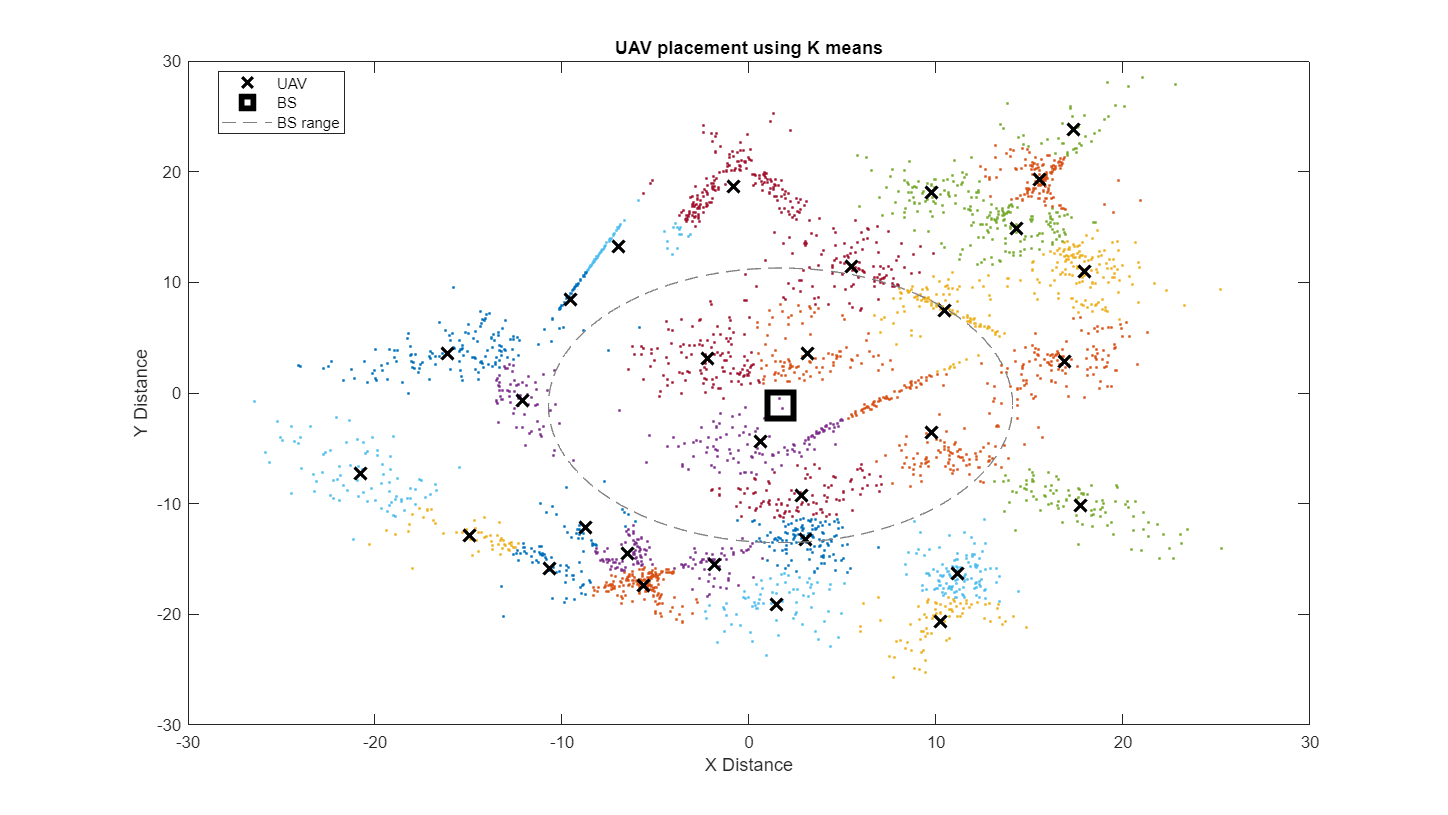

x_bs = mean(centroids(:, 1));
y_bs = mean(centroids(:, 2));

syms x
capacity_bs = bw_bs*log(1 + P_bs/((x^2 + (h_bs)^2)*var_n));
eqn = capacity_bs == capacity_thresh;
r_bs = solve(eqn, x);
r_bs = abs(r_bs(1,1));
th = 0:pi/50:2*pi;
x_circle = x_bs + r_bs * cos(th);
y_circle = y_bs + r_bs * sin(th);

htmlGray = [128 128 128]/255;

figure('Name', 'UAV placement using K means', 'units','normalized','outerposition', [0 0 1 1]);
gscatter(X, Y, idx);
hold on;
p_centroids = plot(centroids(:,1), centroids(:,2), 'kx', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName','UAV'); 
bs_range = plot(x_circle, y_circle, '--', 'Color', htmlGray, 'DisplayName', 'BS range');
bs_pos = plot(x_bs, y_bs, 'ksquare', 'MarkerSize', 20, 'LineWidth', 5, 'DisplayName','BS');
hold off;

leg = [p_centroids, bs_pos, bs_range];
legend(leg,'UAV','BS', 'BS range');
title('UAV placement using K means');
xlabel('X Distance');
ylabel('Y Distance');

optimal_data = zeros(num_of_centroids, 5);
for i=1:num_of_centroids
    [optimal_data(i,1), optimal_data(i,2), optimal_data(i,3), optimal_data(i,4), optimal_data(i,5)] = optimize_pow_height_cluster(k_means_clusters{i}, centroids(i,:), power_threshold, height_threshold, alpha, chan_capacity_thresh, bw_uav, var_n);
end

Solving problem using fmincon.

Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Consider enabling the interior point method feasibility mode.


Solving problem using fmincon.



uav_1 = [];
uav_2 = [];
numbered_labelling_uav = (2:31)';
numbered_labelling_uav = num2str(numbered_labelling_uav);
numbered_labelling_bs = '1';
dx = 0.8; dy = 0.8;

for i=1:num_of_centroids
    points = optimal_points(x_bs, y_bs, centroids(i,1), centroids(i,2), P_bs, P_uav, bw_bs, bw_uav, optimal_data(i,2), h_bs, h_relay, capacity_thresh, var_n);
    uav_1 = [uav_1; points(1, :)];
    uav_2 = [uav_2; points(2, :)];
end

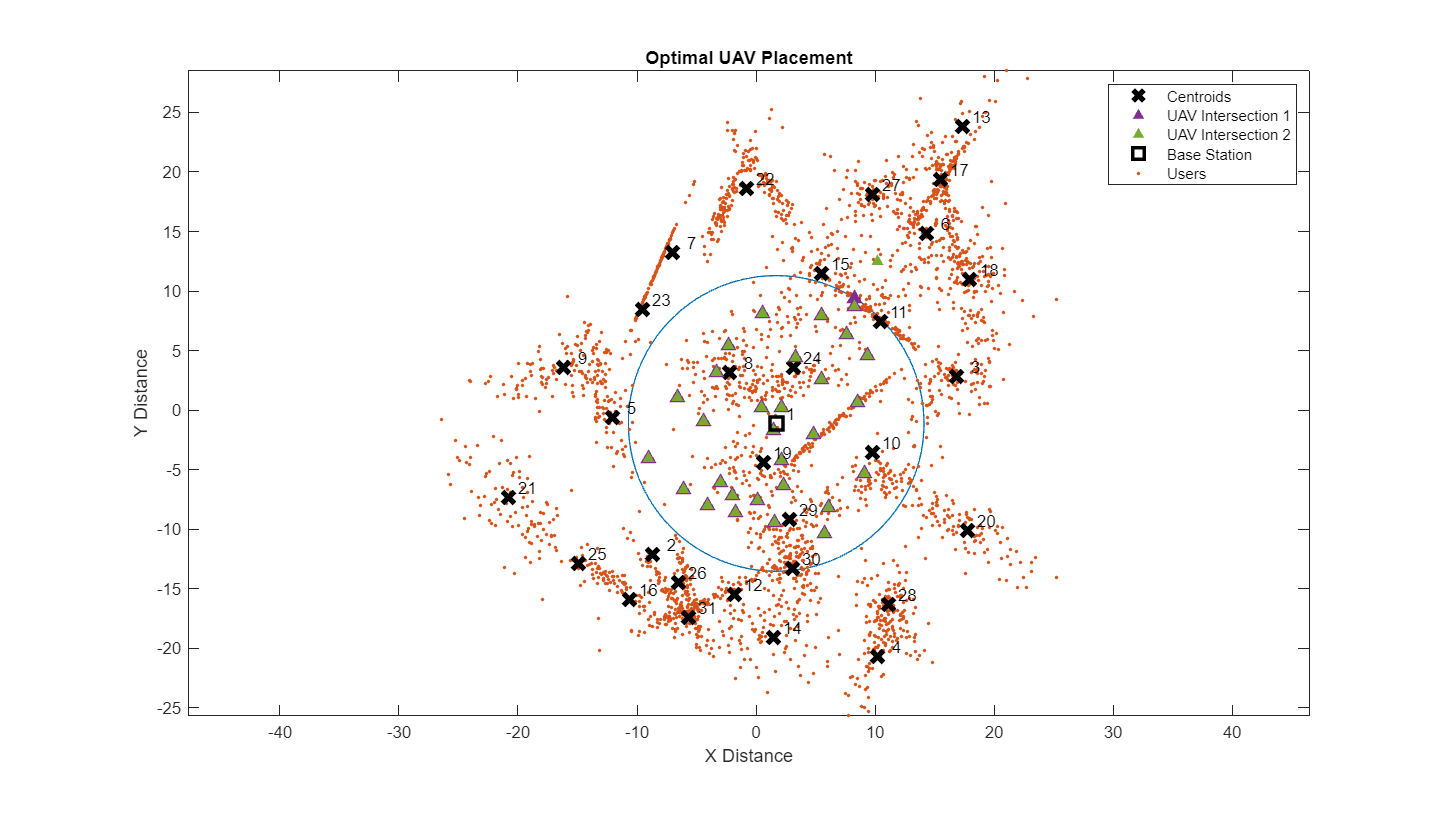

figure('Name', 'Optimal UAV Placement', 'units','normalized','outerposition', [0 0 1 1]);

th = 0:pi/50:2*pi;
x_circle = x_bs + r_bs * cos(th);
y_circle = y_bs + r_bs * sin(th);
plot(x_circle, y_circle);
hold on;

users = scatter(X, Y, [], '.');
hold on;
p_centroid = plot(centroids(:,1), centroids(:,2), 'kx', 'MarkerSize', 10, 'LineWidth', 3, 'DisplayName', 'Centroids'); 
hold on;
p_uav_1 = scatter(uav_1(:,1), uav_1(:,2), 70, '^', 'filled');
hold on;
p_uav_2 = scatter(uav_2(:,1), uav_2(:,2), 40, '^', 'filled');
hold on;
p_center = plot(x_bs, y_bs, 'ks', 'MarkerSize', 10, 'LineWidth', 3);
hold off;
axis equal;

legend([p_centroid, p_uav_1, p_uav_2, p_center, users], 'Centroids','UAV Intersection 1', 'UAV Intersection 2', 'Base Station', 'Users');
title('Optimal UAV Placement');
xlabel('X Distance');
ylabel('Y Distance');
text(centroids(:,1) + dx, centroids(:,2) + dy, numbered_labelling_uav);
text(x_bs + dx, y_bs + dy, numbered_labelling_bs);
hold off;

function [data] = generate_data(num_of_clusters, start_range_mean, end_range_mean, start_range_var, end_range_var, data_points_per_cluster)

    data = [];

    for i=1:num_of_clusters
        
        mu = start_range_mean + (end_range_mean - start_range_mean).* rand(2,1);

        while (true)
          A = -1 + 2.*rand(2, 2);
          if (rank(A) == 2)
              break; 
          end    
        end
        sigma = A' * A; 
        sigma = start_range_var + (end_range_var - start_range_var).*sigma;

        data_per_cluster = mvnrnd(mu, sigma, data_points_per_cluster);
        data = [data; data_per_cluster];
    end
end 

Optimal height, power cluster

function [pow, height, rad, users_served, total_users] = optimize_pow_height_cluster(k_means_cluster, ... 
    centroid, p_thresh, h_thresh, alpha, channel_cap_thresh, bw_uav, var_n)
    
    prob = optimproblem('ObjectiveSense','min');
    x = optimvar('x',2,1);
    prob.Objective = alpha*x(1) + (1-alpha)*x(2);
    
    cons1 = x(1) <= p_thresh;
    cons2 = x(2) >= h_thresh; 
    cons3 = x(1) >= 0;
    
    prob.Constraints.cons1 = cons1;
    prob.Constraints.cons2 = cons2;
    prob.Constraints.cons3 = cons3;
    
    dist = (k_means_cluster(:, 1) - centroid(1,1)) .^ 2 +(k_means_cluster(:, 2) - centroid(1,2)) .^ 2;
    
    [~, id] = sort(dist(:,1));
    dist = dist(id, :);
    
    K = size(k_means_cluster, 1);
    
    pow = 0;
    height = 0;
    rad = 0;
    users_served = 0;
    total_users = K;
    
    for i=K:-1:1
        cons4 = bw_uav * log(1+x(1)/((dist(i,1) + x(2)^2)*var_n))>=channel_cap_thresh;
        prob.Constraints.cons4 = cons4;
        x0.x = [p_thresh, 2*h_thresh];
        sol = solve(prob, x0);
        check = infeasibility(cons1, sol) || infeasibility(cons2, sol) || infeasibility(cons3, sol) || infeasibility(cons4, sol);
        if (check==0)
            pow = sol.x(1,1);
            height = sol.x(2, 1);
            rad = sqrt(dist(i, 1));
            users_served = i;
            break;
        end
    end 
end    

Optimal points for relay UAVs

function [points] = optimal_points(x_bs, y_bs, x_c, y_c, P_bs, P_uav, ...
    bw_bs, bw_uav, h_uav, h_bs, h_relay, capacity_thresh, var_n)

    d = abs(sqrt((x_c - x_bs)^2 + (y_c -  y_bs)^2));
    theta = atan2((y_c - y_bs), (x_c - x_bs));

    syms x
    capacity_bs = bw_bs*log(1 + P_bs/((x^2 + (h_relay-h_bs)^2) * var_n));
    capacity_uav = bw_uav*log(1 + P_uav/(((x-d)^2 + (h_uav-h_relay)^2) * var_n));
    
    intersection_bs_thresh = vpasolve(capacity_bs == capacity_thresh, x, [0, d]);
    intersection_uav_thresh = vpasolve(capacity_uav == capacity_thresh, x, [0, d]);
    intersection_both_capacities = vpasolve(capacity_uav == capacity_bs, x, [0, d]);
    val_intersection_both_capacities = subs(capacity_uav, intersection_both_capacities);
  
    if (val_intersection_both_capacities > capacity_thresh)
        x1 = x_bs + cos(theta) * intersection_both_capacities;
        y1 = y_bs + sin(theta) * intersection_both_capacities;
        points = [x1, y1; x1, y1];
    elseif (isempty(intersection_bs_thresh) || isempty(intersection_uav_thresh))
        points = [x_bs, y_bs; x_bs, y_bs];
    else
        x1 = x_bs + cos(theta) * intersection_bs_thresh;
        y1 = y_bs + sin(theta) * intersection_bs_thresh;
        x2 = x_bs + cos(theta) * intersection_uav_thresh;
        y2 = y_bs + sin(theta) * intersection_uav_thresh;
        points = [x1, y1; x2, y2];
    end
end
